# Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizi una cifra di merito.

Si possono scegliere tanti vincoli e cifre di merito, ma la struttura base rimane simile.

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

clear all;close all;clc;
load modello_jnt2.mat
sys_vel_motore=tf(modello_giunto(2,1));

Inserisco il filtro notch (volendo si può pensare di ottimizzare anche i coefficienti del filtro

wn=290;
xci_z=0.1; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.7;
s=tf('s');
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2);
P=sys_vel_motore*notch;

La cifra di merito è


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


(alternativa $J=-\omega_c$ massimizzare la pulsazione di taglio)

con $\omega_c$ la frequenza (pulsazione) di taglio, e $\omega_{c,des}$ il valore desiderato.

Le incognite del problema sono $x=[K_p,\;K_i]$

wc_des=200;
J=@(x)pivel_cost_function(x,P,wc_des);

I vincoli sono (potete modificarli, aggiungerne, toglierne)

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

MS=1.4;
wh=2000;
Fh_max=0.1;
wl=0.1;
Dh_max=0.1;

w_vector=logspace(-3,3)'; % [10^-3,10^3]
w_vector=sort([w_vector;wl;wh]);

nlcon=@(x)pivel_constraints(x,P,w_vector,MS,wh,Fh_max,wl,Dh_max);

Risolvo il problema con fmincon, la soluzione è locale.

Impongo che $K_p\in[0.01,10000]$ e $K_i\in[0.01,10000]$

x0=[1,0.1];
x=fmincon(J,x0,[],[],[],[],[0.01 0.01],[10000 10000],nlcon)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x = 	1.0e+03 *

    0.5020   10.0000


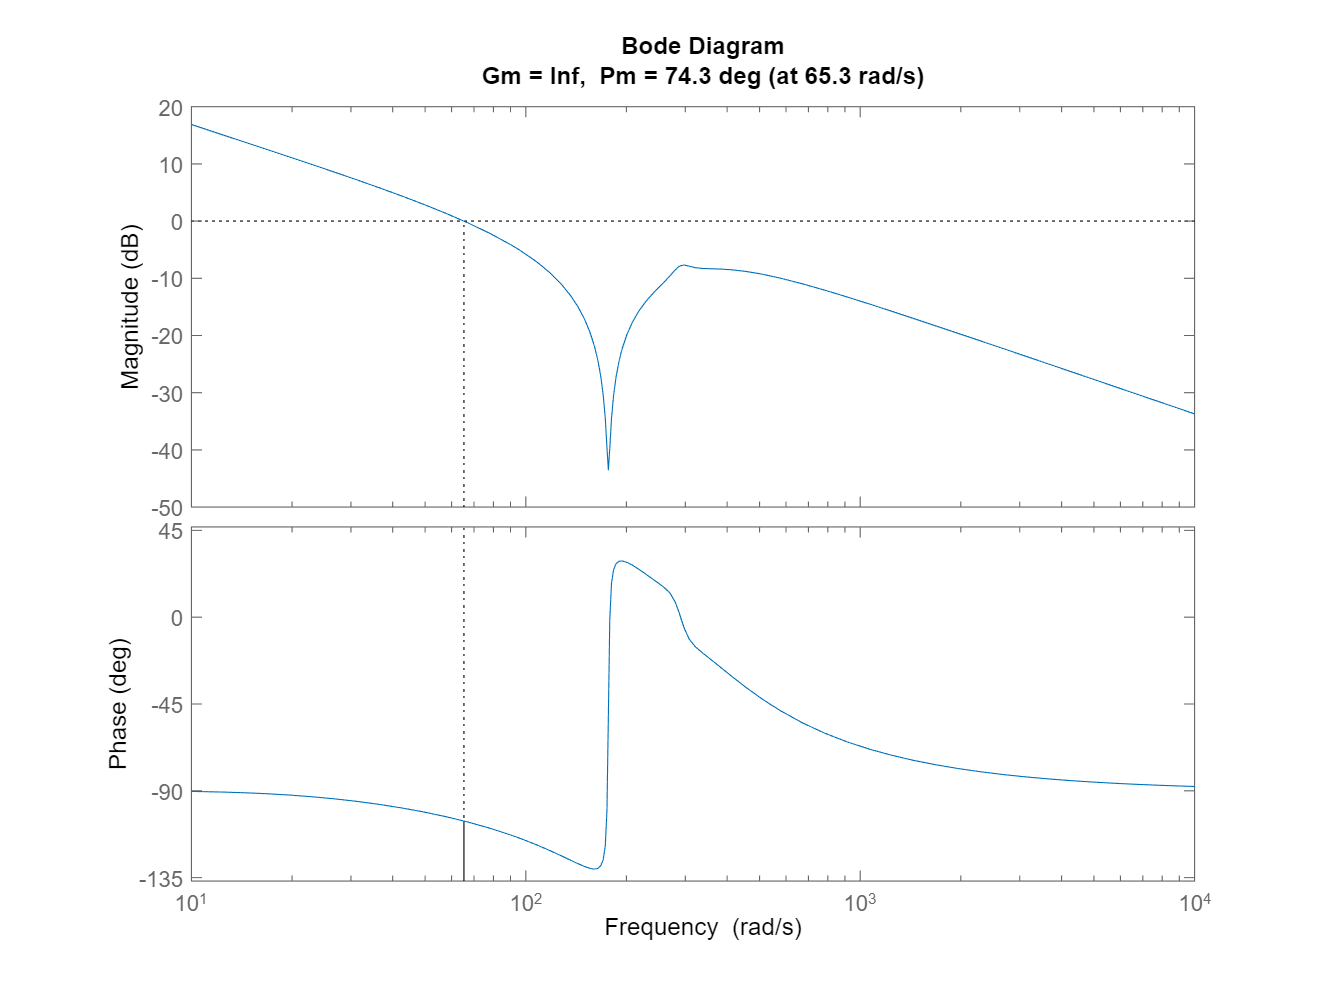

Kp=x(1);
Ki=x(2);
C=tf([Kp Ki],[1 0]);
margin(C*P)

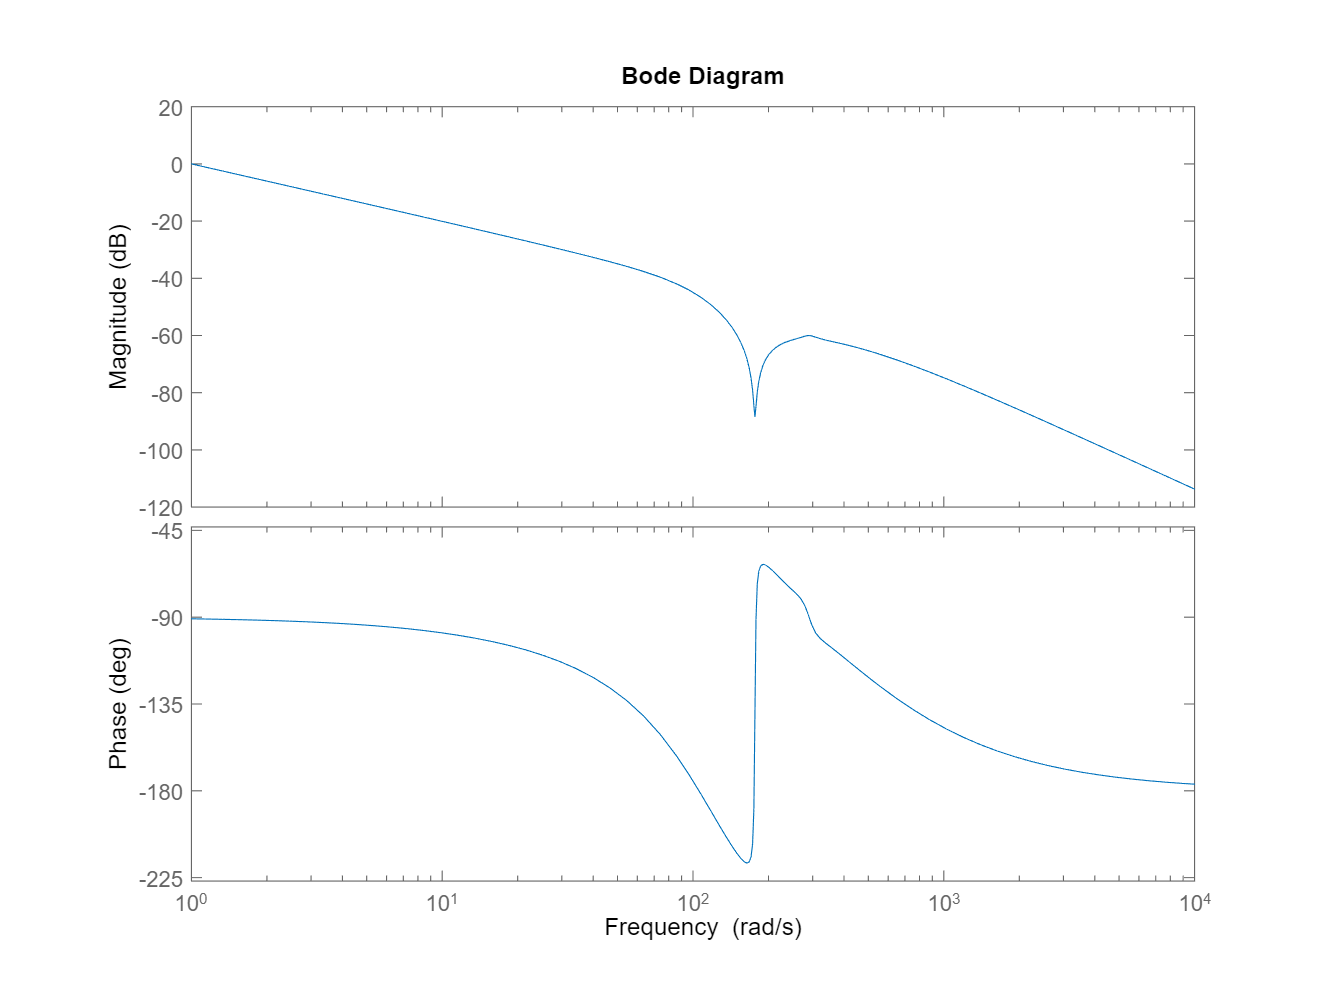


anello_chiuso_velocita=feedback(sys_vel_motore*notch*C,1);

anello_aperto_posizione=1/s*anello_chiuso_velocita;
figure
bode(anello_aperto_posizione)